% 1st order
clc; clear; close all
tic
format long

%% parameter settings
tol = 1e-5;
kmax = 20000;
N = 129;
x = linspace(-1, 1, N);
z = linspace(0, 2, N);
[X, Z] = meshgrid(x, z);

%% examples
% c_exact = 3 - 2.5 * exp(-X.^2 / 2);
% c_exact = ones(N);
c_exact = 3 - (1/2)*exp(-(X.^2 + (Z-0.5).^2)/0.5.^2) - exp(-(X.^2 + (Z-1.25).^2)/0.5.^2);
% load c_data/example_4
% load D:\桌面\codes\examples&results\results\example_4\c

%% source point
fixed_pt_list = [];
for m = 1:4
    for n = 1:4
        fixed_pt_list = [fixed_pt_list; 0, m*25, n*25];
    end
end  


%% iteration
I = N;
J = N;
dx = (x(end)-x(1)) / (I-1); dy = (z(end) - z(1)) / (J-1);

niu = 1;
c0 = c_solver2(c_exact, zeros(I, J), dx, dy, niu);
c = c0;

energy = 1e9;
relative_error = 1e9;
alpha_f = 1e-4; alpha_0 = 0.1;
for k = 1: kmax
    
    energy_p = 0;
    cstar = 0;
    parfor p_num = 1:size(fixed_pt_list, 1)
        T = TravelTime_solver(c, fixed_pt_list(p_num, :), dx, dy, I, J);
        T_star = TravelTime_solver(c_exact, fixed_pt_list(p_num, :), dx, dy, I, J);
        energy_p = energy_p + EnergyFun(T, T_star, dx, dy);
        cstar = cstar + cStarSolver(T, T_star, dx, I, J, c);
    end
    
    if energy_p < 0.0025
        break
    end

    energy = [energy, energy_p];
    relative_error = [relative_error, norm(c-c_exact)/norm(c_exact)];
    if mod(k, 10) == 0
       disp(k)
       disp(norm(cstar)*dx*dy)
    end

        alpha = 0.5;
    % alpha = alpha_f + 0.5*(alpha_0 - alpha_f) * (1 + cos(pi*k / kmax));
    c = c + alpha * cstar;
   
end

    10


     7.250753880365213e-05


    20


     5.713839990057008e-05


    30


     4.563379667742745e-05


    40


     3.688725841100654e-05


    50


     3.016629355775944e-05


    60


     2.496511980943031e-05


    70


     2.092112291183372e-05


    80


     1.776643638408016e-05


    90


     1.529862310993067e-05


   100


     1.336294218019224e-05


   110


     1.184073639786090e-05


   120


     1.064186117534267e-05


   130


     9.699602646101076e-06


   140


     8.966164091364599e-06


   150


     8.408611581656984e-06


   160


     8.002494932835677e-06


   170


     7.722298678682274e-06


   180


     7.535608529911785e-06


   190


     7.408653167480465e-06


   200


     7.315166455949541e-06


   210


     7.238665718917628e-06


   220


     7.170005781573360e-06


   230


     7.104458425757469e-06


   240


     7.039723577977462e-06


   250


     6.974786676089350e-06


   260


     6.909292351788628e-06


   270


     6.843212477662614e-06


   280


     6.776667816125650e-06


   290


     6.709834038949461e-06


   300


     6.642895186092671e-06


   310


     6.576018233534405e-06


   320


     6.509349690857042e-06


   330


     6.443006472793415e-06


   340


     6.377083139973292e-06


   350


     6.311649921050633e-06


   360


     6.246762198272165e-06


   370


     6.182457879925186e-06


   380


     6.118761705025735e-06


   390


     6.055692193104373e-06


   400


     5.993259540814625e-06


   410


     5.931466644974063e-06


   420


     5.870313398459307e-06


   430


     5.809798577352915e-06


   440


     5.749915558289727e-06


   450


     5.690658192555563e-06


   460


     5.632019427407120e-06


   470


     5.573991004236214e-06


   480


     5.516563710145718e-06


   490


     5.459729685421073e-06


   500


     5.403480352419581e-06


   510


     5.347807918308686e-06


   520


     5.292703044458454e-06


   530


     5.238157670931054e-06


   540


     5.184164186269990e-06


   550


     5.130715326799130e-06


   560


     5.077804384335581e-06


   570


     5.025424029691260e-06


   580


     4.973566917849985e-06


   590


     4.922226679925147e-06


   600


     4.871397099853045e-06


   610


     4.821072352920770e-06


   620


     4.771246761414752e-06


   630


     4.721914241669477e-06


   640


     4.673069336888576e-06


   650


     4.624706868779147e-06


   660


     4.576821272753799e-06


   670


     4.529407695733909e-06


   680


     4.482461261221456e-06


   690


     4.435977253289607e-06


   700


     4.389950835174970e-06


   710


     4.344377339408458e-06


   720


     4.299252295287253e-06


   730


     4.254571304177268e-06


   740


     4.210330177401480e-06


   750


     4.166524529681484e-06


   760


     4.123150221604535e-06


   770


     4.080203238939878e-06


   780


     4.037679693015229e-06


   790


     3.995575530045221e-06


   800


     3.953886776254901e-06


   810


     3.912609690600620e-06


   820


     3.871740462296263e-06


   830


     3.831275387281360e-06


   840


     3.791210836054583e-06


   850


     3.751543107285831e-06


   860


     3.712268631591933e-06


   870


     3.673383983326895e-06


   880


     3.634885703732276e-06


   890


     3.596770373157121e-06


   900


     3.559034511960010e-06


   910


     3.521674742427214e-06


   920


     3.484687704382897e-06


   930


     3.448070126458061e-06


   940


     3.411818727822463e-06


   950


     3.375930272610917e-06


   960


     3.340401567356332e-06


   970


     3.305229462344874e-06


   980


     3.270410888601116e-06


   990


     3.235942717507598e-06


        1000


     3.201821820463765e-06


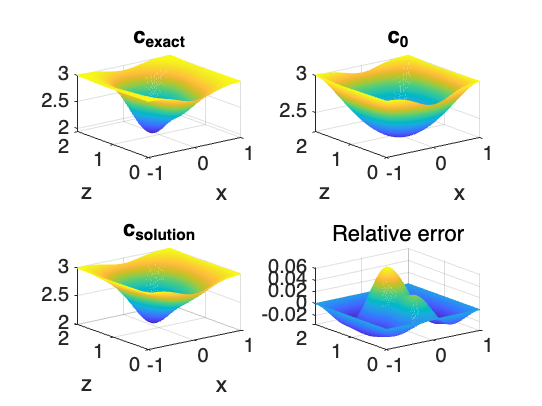


%% results and visualization
figure
subplot(2, 2, 1)
mesh(x, z, c_exact)
xlabel x
ylabel z
title('c_{exact}', 'FontWeight','bold')
subplot(2, 2, 2)
mesh(x, z, c0)
xlabel x
ylabel z
title('c_0', 'FontWeight','bold')
subplot(2, 2, 3)
mesh(x, z, c)
xlabel x
ylabel z
title('c_{solution}', 'FontWeight','bold')
subplot(2, 2, 4)
mesh(x, z, (c-c_exact)./c_exact)
title('Relative error')

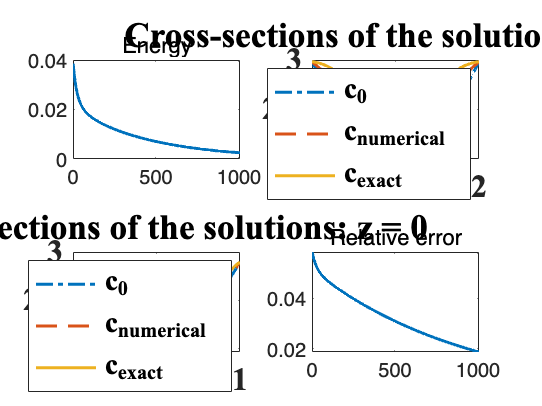


figure
subplot(2, 2, 1)
plot(energy(2:end), 'linewidth', 1.5)
title('Energy')

subplot(2, 2, 2)
plot(z, c0(60, :), '-.', 'linewidth', 1.5)
hold on
plot(z, c(60, :), '--', 'linewidth', 1.5)
hold on
plot(z, c_exact(60, :), 'linewidth', 1.5)
legend('c_0', 'c_{numerical}', 'c_{exact}')
title('Cross-sections of the solutions: x = 0', 'FontWeight','bold')
set(gca, 'FontName','Times New Roman', 'FontSize',16, 'FontWeight','bold');

subplot(2, 2, 3)
plot(x, c0(:, 60), '-.', 'linewidth', 1.5)
hold on
plot(x, c(:, 60), '--', 'linewidth', 1.5)
hold on
plot(x, c_exact(:, 60), 'linewidth', 1.5)
legend('c_0', 'c_{numerical}', 'c_{exact}')
title('Cross-sections of the solutions: z = 0', 'FontWeight','bold')
set(gca, 'FontName','Times New Roman', 'FontSize',16, 'FontWeight','bold');

subplot(2, 2, 4)
plot(relative_error(2:end), 'linewidth', 1.5)
title('Relative error')


toc

历时 156.748236 秒。
